% Developped and written by Emmanuelle CHAIGNEAU
% Laboratory of Serge Charpak

% Script to fit fUS CBV response to CO2 stimulation

% load('DataToFit.mat');
% load('Time.mat');

TStart = 5;                     % (in s)
TStartStim = 10;                % (in s)
TEndStim = 20;                  % (in s)
TStop = 50;                     % (in s)
ThresholdLevel = 0.1;           % (between 0 and 1)
Smoothing = 15;                 % number of points used for smoothing data and detecting the min
DataSmooth = 1;                 % to use smoothed data for fitting : 1
                                % to use raw data for fitting : 0

% crop recording
IdxCrop=(Time >= TStart) & (Time <= TStop);
CropedDataToFit=DataToFit(IdxCrop);
CropedTime=Time(IdxCrop);

% average baseline
IdxBaseline = (Time >= TStart) & (Time <= TStartStim);
Baseline =  DataToFit(IdxBaseline);
fUSBaseline = mean(Baseline)

fUSBaseline = -4.1016e-04

% Find min of DataToFit
SmoothDataToFit = smooth(CropedDataToFit,Smoothing);
[MinSmoothDataToFit, IdxSmoothMinDataToFit] = min(SmoothDataToFit);
TimeMinDataToFit = CropedTime(IdxSmoothMinDataToFit) 

TimeMinDataToFit = 13.4000


% Plot smoothing with data.
figure( 'Name', 'smoothing' );
plot(Time, DataToFit, '.', 'color', 'c') ;
hold on
plot(CropedTime, SmoothDataToFit)
legend( 'data', 'smoothing', 'Location', 'NorthEast', 'Interpreter', 'none' );

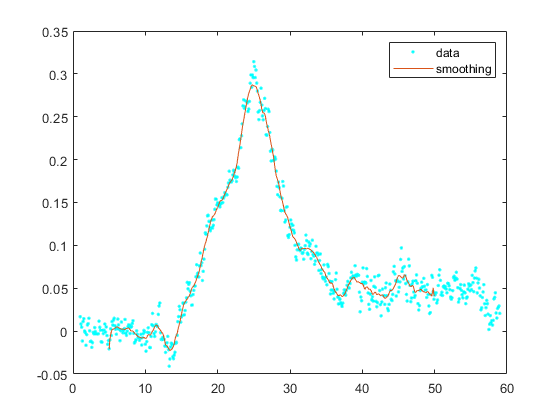

hold off


% Setup data to fit 
IndexFit1 = (CropedTime >= (TimeMinDataToFit - 12)) & (CropedTime <= TimeMinDataToFit);
IndexFit2 = (CropedTime > TimeMinDataToFit) & (CropedTime <= TStop);

if DataSmooth == 0
    [xData1, yData1] = prepareCurveData( CropedTime(IndexFit1), DataToFit(IndexFit1));
    [xData2, yData2] = prepareCurveData( CropedTime(IndexFit2), DataToFit(IndexFit2));
else
    [xData1, yData1] = prepareCurveData( CropedTime(IndexFit1), SmoothDataToFit(IndexFit1));
    [xData2, yData2] = prepareCurveData( CropedTime(IndexFit2), SmoothDataToFit(IndexFit2));
end

% Fit  ydata1
% Set up fittype and options.
ft1 = fittype( 'a1*(x-T1)^2 + b1*(x-T1) +c1', 'independent', 'x', 'dependent', 'y' );
opts1 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts1.Display = 'Off';
opts1.Lower = [0 0 -Inf fUSBaseline];
opts1.StartPoint = [10 0.01 -0.1 fUSBaseline];
opts1.Upper = [Inf Inf Inf fUSBaseline];

% Fit model to data.
[fitresult1, gof1] = fit( xData1, yData1, ft1, opts1 )

fitresult1 =      General model:
     fitresult1(x) = a1*(x-T1)^2 + b1*(x-T1) +c1
     Coefficients (with 95% confidence bounds):
       T1 =       59.76  (-1969, 2089)
       a1 =   6.162e-06  (-0.0002721, 0.0002844)
       b1 =   0.0003502  (-0.002848, 0.003548)
       c1 =  -0.0004102  (fixed at bound)

gof1 = struct with fields:
           sse: 0.0040
       rsquare: 0.0699
           dfe: 82
    adjrsquare: 0.0472
          rmse: 0.0069


fitcoeffvals1= coeffvalues(fitresult1);

T1 = fitcoeffvals1(1)

T1 = 59.7626

a1 = fitcoeffvals1(2)

a1 = 6.1617e-06

b1 = fitcoeffvals1(3)

b1 = 3.5016e-04

c1 = fitcoeffvals1(4)

c1 = -4.1016e-04



% Fit  ydata2
% Set up fittype and options.
ft2 = fittype( '-a2*(exp(-(x-b2)/T2)-1)+c2', 'independent', 'x', 'dependent', 'y' );
opts2 = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts2.Display = 'Off';
opts2.Lower = [0 0 TimeMinDataToFit a1*(TimeMinDataToFit-T1)^2+b1*(TimeMinDataToFit-T1)+c1];
opts2.StartPoint = [1 20 TimeMinDataToFit a1*(TimeMinDataToFit-T1)^2+b1*(TimeMinDataToFit-T1)+c1];
opts2.Upper = [Inf Inf TimeMinDataToFit a1*(TimeMinDataToFit-T1)^2+b1*(TimeMinDataToFit-T1)+c1];

[fitresult2, gof2] = fit( xData2, yData2, ft2, opts2 )

fitresult2 =      General model:
     fitresult2(x) = -a2*(exp(-(x-b2)/T2)-1)+c2
     Coefficients (with 95% confidence bounds):
       T2 =       2.155  (0.8952, 3.415)
       a2 =      0.1121  (0.1037, 0.1204)
       b2 =        13.4  (fixed at bound)
       c2 =     -0.0034  (fixed at bound)

gof2 = struct with fields:
           sse: 1.8609
       rsquare: 0.1059
           dfe: 364
    adjrsquare: 0.1035
          rmse: 0.0715


fitcoeffvals2= coeffvalues(fitresult2);

T2 = fitcoeffvals2(1)

T2 = 2.1552

a2 = fitcoeffvals2(2)

a2 = 0.1121

b2 = fitcoeffvals2(3)

b2 = 13.4000

c2 = fitcoeffvals2(4)

c2 = -0.0034

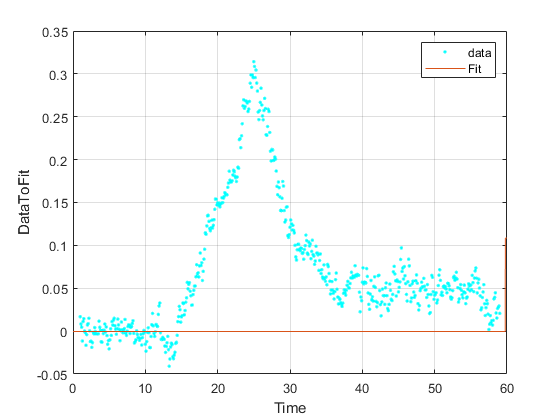

% plot and nomalize

TTime = (0:0.01:60)';
FitTTime = zeros(6001,1);

for icnt = 1:6001
    FitTTime(icnt) = FitfUSCarotide(fUSBaseline, TimeMinDataToFit, fitcoeffvals1, fitcoeffvals2, TTime(icnt));
end

% Plot fit with data.
figure( 'Name', 'CalciumDependantFluoFit' );
h = plot(Time, DataToFit, '.', 'color', 'c') ;
hold on
plot(TTime, FitTTime),
legend('data', 'Fit', 'Location', 'NorthEast');
hold off

% Label axes
xlabel( 'Time' );
ylabel( 'DataToFit');
grid on

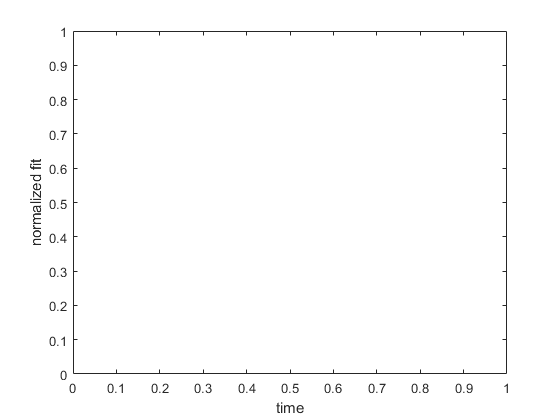

% normalized fit
[MinFit, IdxMin] = min(FitTTime);
NormFit = -(FitTTime - fUSBaseline) / (MinFit - fUSBaseline);

% plot noorm fit 
figure( 'Name', 'Normalized Fit' );
h2 = plot( TTime, NormFit );
% Label axes
xlabel( 'time');
ylabel( 'normalized fit');

% Threshold calculation
IndexBelowThreshold = (NormFit >= -ThresholdLevel);
IndexBeforeMin = IndexBelowThreshold(1:IdxMin);
TimeBeforeThreshold = TTime(IndexBeforeMin);
[TimeThrehold, IdxTimeThrehold] = max(TimeBeforeThreshold);
TimeThrehold;

IndexBelowThreshold10 = (NormFit >= -0.1);
IndexBeforeMin10 = IndexBelowThreshold10(1:IdxMin);
TimeBeforeThreshold10 = TTime(IndexBeforeMin10);
[TimeThrehold10, IdxTimeThrehold10] = max(TimeBeforeThreshold10);
TimeThrehold10


TimeThrehold10 =

     []




IndexBelowThreshold15 = (NormFit >= -0.15);
IndexBeforeMin15 = IndexBelowThreshold15(1:IdxMin);
TimeBeforeThreshold15 = TTime(IndexBeforeMin15);
[TimeThrehold15, IdxTimeThrehold15] = max(TimeBeforeThreshold15);
TimeThrehold15


TimeThrehold15 =

     []




IndexBelowThreshold20 = (NormFit >= -0.2);
IndexBeforeMin20 = IndexBelowThreshold20(1:IdxMin);
TimeBeforeThreshold20 = TTime(IndexBeforeMin20);
[TimeThrehold20, IdxTimeThrehold20] = max(TimeBeforeThreshold20);
TimeThrehold20


TimeThrehold20 =

     []




TimeThrehold101520 = [TimeThrehold10 ; TimeThrehold15 ; TimeThrehold20];

function y = FitfUSCarotide(fUSBaseline, TimeMinDataToFit, fitcoeffvals1, fitcoeffvals2, x)
   if x <= fitcoeffvals1(1)
       y = fUSBaseline; 
   elseif x <= TimeMinDataToFit
       y = fitcoeffvals1(2)*(x-fitcoeffvals1(1))^2 + fitcoeffvals1(3)*(x-fitcoeffvals1(1)) + fitcoeffvals1(4); 
   else
       y = -fitcoeffvals2(2)*(exp(-(x-TimeMinDataToFit)/fitcoeffvals2(1))-1) + fitcoeffvals2(4);
   end
end